# Impact of Downsampling on sEMG signals

clear;
clc;
close all;

## 1. Loading Data

% Folder containing .mat files
folderPath = 'C:\Users\Surya\Desktop\sEMG Sampling Rate Analysis\Data';

% List of all .mat files in the folder
matFiles = dir(fullfile(folderPath, '*.mat'));

## 2. Loading 45.mat file (File containing data collected in 45 degrees shoulder angle)

% Shoulder Angle = 45 degrees. (Most relaxed position)
i = 2;
disp(matFiles(i).name);

45.mat


matFileName = fullfile(folderPath, matFiles(i).name);
load(matFileName);

## 3. Selecting a trial from Normal pace and Fast pace for single signal analysis

% Selecting a Trial.
j =121;
% Extract the sEMG signals from the specified channels
channels_normal_pace = [Data.Trials.movements(j).sources.signals.signal_1.data ...
            Data.Trials.movements(j).sources.signals.signal_2.data ...
            Data.Trials.movements(j).sources.signals.signal_3.data ...
            Data.Trials.movements(j).sources.signals.signal_4.data];

j =135;
% Extract the sEMG signals from the specified channels
channels_fast_pace = [Data.Trials.movements(j).sources.signals.signal_1.data ...
            Data.Trials.movements(j).sources.signals.signal_2.data ...
            Data.Trials.movements(j).sources.signals.signal_3.data ...
            Data.Trials.movements(j).sources.signals.signal_4.data];

## 4. Sampling Rate

% Sampling rate
fs = 4000;
% Number of seconds to be discarded.
t = 3;

## 5. Segmenting the signal

% Each Normal pace trial has: 3s (Rest) - 6s (Action) - 3s (Release)
% Each Fast pace trial has: 3s (Rest) - 4s (Action) - 3s (Release)
% Removing 3s Rest and 3s Release from each channel.

numValuesToRemove = t*fs;
activity_normal_pace = channels_normal_pace(numValuesToRemove + 1:end-numValuesToRemove, :);
activity_fast_pace = channels_fast_pace(numValuesToRemove + 1:end-numValuesToRemove, :);

## 6. Applying anti-aliasing filter

% downsampling factor
downsampling_factor = 1.5;

% new sampling rate after downsampling
new_sampling_rate = fs / downsampling_factor;

% cutoff frequency for the anti-aliasing filter
cutoff_frequency = new_sampling_rate / 2;

% low-pass Butterworth filter for anti-aliasing
filter_order = 8;
[b, a] = butter(filter_order, cutoff_frequency / (fs / 2), 'low');

% Appling anti-aliasing filter to the original signal
filtered_signal = filtfilt(b, a, activity_normal_pace);

% Downsampled from 6sec to 4sec
downsampled_signal = resample(filtered_signal, 4, 6);

## 7. Plotting Signals

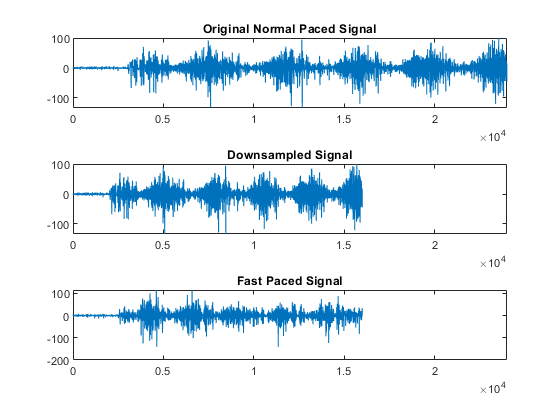

% number of rows and columns for the subplot grid
numRows = 3;
numCols = 1;

% Plotting the signals
figure;
subplot(numRows, numCols, 1);
plot(activity_normal_pace(:,1));
title('Original Normal Paced Signal');
xlim([0, 24000]);

subplot(numRows, numCols, 2);
plot(downsampled_signal(:,1));
title('Downsampled Signal');
xlim([0, 24000]);

subplot(numRows, numCols, 3);
plot(activity_fast_pace(:,1));
title('Fast Paced Signal');
xlim([0, 24000]);


spacing = 0.04;
subplot('Position', [0.1, 0.1, 0.85, 0.85]);
axis off;

set(gcf, 'Position', [100, 100, 800, 600]);

## 8. Frequency Responses

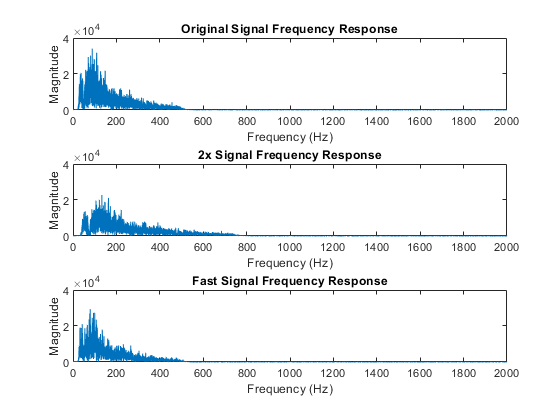

% Frequency Response
figure;

fft_original_1x = abs(fft(activity_normal_pace));
fft_downsampled_signal = abs(fft(downsampled_signal));
fft_original_2x = abs(fft(activity_fast_pace));

% frequency response of the signals
N = size(activity_normal_pace, 1);
frequencies = linspace(0, fs/2, N/2 + 1);

% Plotting the frequency responses in subplots
subplot(numRows, numCols, 1);
plot(frequencies, fft_original_1x(1:N/2 + 1, 1));
title('Original Signal Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0, 40000]);

N = size(downsampled_signal, 1);
frequencies = linspace(0, fs/2, N/2 + 1);

subplot(numRows, numCols, 2);
plot(frequencies(1:2:end, :), fft_downsampled_signal(1:N/2 + 1, 1));
title('2x Signal Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0, 40000]);

N = size(activity_fast_pace, 1);
frequencies = linspace(0, fs/2, N/2 + 1);

subplot(numRows, numCols, 3);
plot(frequencies, fft_original_2x(1:N/2 + 1, 1));
title('Fast Signal Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0, 40000]);


spacing = 0.04;
subplot('Position', [0.1, 0.1, 0.85, 0.85]);
axis off;

set(gcf, 'Position', [100, 100, 800, 600]);

## 9. Correlation between signals and downsampled signals

padded_signal = [activity_fast_pace; zeros(8000,4)];

% Calculate the correlation matrix
correlation_matrix = corr(activity_normal_pace, padded_signal);

% Display the correlation matrix
disp('Correlation Matrix:');

Correlation Matrix:


disp(correlation_matrix);

    0.0272    0.0256    0.0086   -0.0082
   -0.0064   -0.0325   -0.0192    0.0098
    0.0081    0.0157   -0.0190    0.0274
   -0.0090    0.0125   -0.0275   -0.0097




% Calculate the correlation matrix
correlation_matrix = corr(downsampled_signal, activity_fast_pace);

% Display the correlation matrix
disp('Correlation Matrix:');

Correlation Matrix:


disp(correlation_matrix);

   -0.0041   -0.0345   -0.0073    0.0115
    0.0154    0.0071   -0.0298    0.0074
    0.0355    0.0019    0.0104   -0.0048
    0.0016   -0.0015   -0.0004    0.0203



## 10. Segregating Normal paced trials and Fast paced trials

arr_normal_activity = [];
arr_downsampled_signal = [];
arr_fast_activity = [];

% Applying the same analysis on all the trials in 45 degrees postures.
% Discarding first trial due to uneven signal lengths.
% Total trials used : 199
for i=2:200
    % Check the length of the data array
    if length(Data.Trials.movements(i).sources.signals.signal_4.data) == 48000
        arr1 = [Data.Trials.movements(i).sources.signals.signal_1.data ...
            Data.Trials.movements(i).sources.signals.signal_2.data ...
            Data.Trials.movements(i).sources.signals.signal_3.data ...
            Data.Trials.movements(i).sources.signals.signal_4.data];
        arr_normal_activity = [arr_normal_activity; arr1(numValuesToRemove + 1:end-numValuesToRemove, :)];
        
        % Anti-aliasing Filter
        filtered_signal = filtfilt(b, a, arr1(numValuesToRemove + 1:end-numValuesToRemove, :));
        
        % Downsampling from 6sec to 4sec
        downsampled_signal = resample(filtered_signal, 4, 6);
        arr_downsampled_signal = [arr_downsampled_signal; downsampled_signal];
        
    else
        arr2 = [Data.Trials.movements(i).sources.signals.signal_1.data ...
            Data.Trials.movements(i).sources.signals.signal_2.data ...
            Data.Trials.movements(i).sources.signals.signal_3.data ...
            Data.Trials.movements(i).sources.signals.signal_4.data];
        arr_fast_activity = [arr_fast_activity; arr2(numValuesToRemove + 1:end-numValuesToRemove, :)];
    end
end

## 11. Calculating Correlation for individual pairs of normal paced, fast paced and downsampled signals

% step sizes
normal_step_size = 24000;
step_size = 16000;

corr_normal_vs_fast = [];
corr_downsampled_vs_fast = [];

for j=1:99
    start_index_normal = (j - 1) * normal_step_size + 1;
    end_index_normal = j * normal_step_size;
    
    start_index = (j - 1) * step_size + 1;
    end_index = j * step_size;
    
    % Loading individual trial.
    activity_normal_pace = arr_normal_activity(start_index_normal:end_index_normal, :);
    downsampled_signal = arr_downsampled_signal(start_index:end_index, :);
    activity_fast_pace = arr_fast_activity(start_index:end_index, :);
    
    padded_signal = [activity_fast_pace; zeros(8000,4)];

    % Calculate the correlation matrix for normal paced trial and fast paced trial.
    correlation_matrix = corr(activity_normal_pace, padded_signal);
    corr_normal_vs_fast = [corr_normal_vs_fast; diag(correlation_matrix)'];
    
    % Calculate the correlation matrix for fast paced signal and downsampled signal.
    correlation_matrix = corr(downsampled_signal, activity_fast_pace);
    corr_downsampled_vs_fast = [corr_downsampled_vs_fast; diag(correlation_matrix)'];
end

## 12. Plots for visualising Channel-wise Correlation for Normal vs Fast Paced signal

### a. Scatter Plot

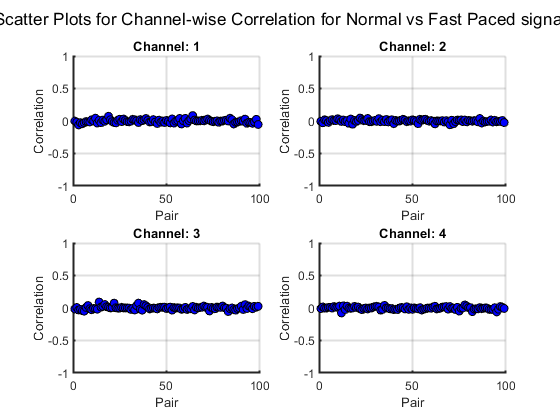

% Scatter Plots for Channel-wise Correlation for Normal vs Fast Paced signal
figure;
for i = 1:4
    subplot(2, 2, i);
    scatter(1:99, corr_normal_vs_fast(:, i), 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b');
    title(['Channel: ' num2str(i)]);
    xlabel('Pair');
    ylabel('Correlation');
    ylim([-1, 1]);
    set(gca, 'LineWidth', 1.5);
    grid on;
end
sgtitle('Scatter Plots for Channel-wise Correlation for Normal vs Fast Paced signal');

### b. Histogram

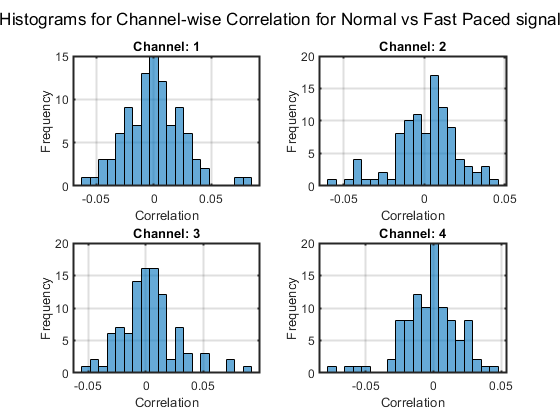

% Histograms for Channel-wise Correlation for Normal vs Fast Paced signal
figure;
for i = 1:4
    subplot(2, 2, i);
    histogram(corr_normal_vs_fast(:, i), 20);
    title(['Channel: ' num2str(i)]);
    xlabel('Correlation');
    ylabel('Frequency');
    set(gca, 'LineWidth', 1.5);
    grid on;
end
sgtitle('Histograms for Channel-wise Correlation for Normal vs Fast Paced signal');

### c. Box plot

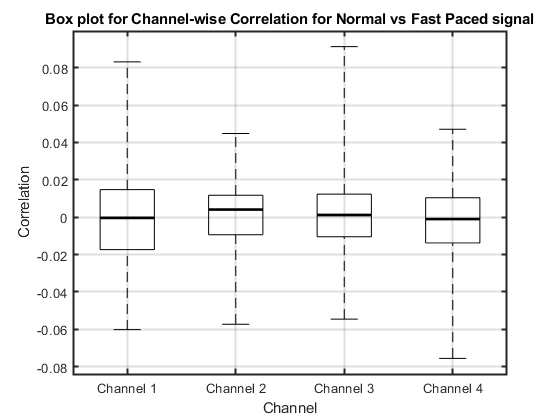

% Box plot for Channel-wise Correlation for Normal vs Fast Paced signal
figure;
h = boxplot(corr_normal_vs_fast, 'Labels', {'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4'}, 'Colors', 'k', 'Whisker',10);
title('Box plot for Channel-wise Correlation for Normal vs Fast Paced signal');
xlabel('Channel');
ylabel('Correlation');

set(findobj(h, 'Tag', 'Median'), 'LineWidth', 2);
set(gca, 'LineWidth', 1.5);
grid on;

## 13. Plots for visualising Channel-wise Correlation for Downsampled vs Fast Paced signal

### a. Scatter plot

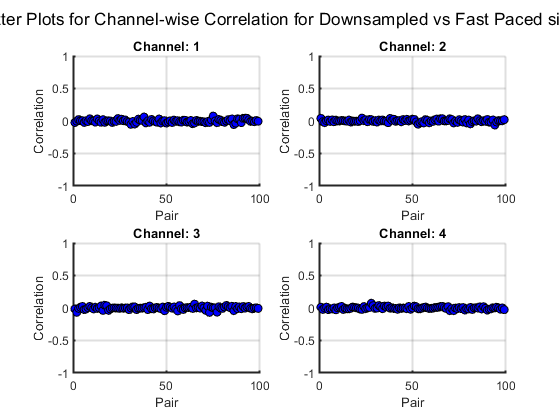

% Scatter plots for Channel-wise Correlation for Downsampled vs Fast Paced signal
figure;
for i = 1:4
    subplot(2, 2, i);
    scatter(1:99, corr_downsampled_vs_fast(:, i), 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b');
    title(['Channel: ' num2str(i)]);
    xlabel('Pair');
    ylabel('Correlation');
    ylim([-1, 1]);
    set(gca, 'LineWidth', 1.5);
    grid on;
end
sgtitle('Scatter Plots for Channel-wise Correlation for Downsampled vs Fast Paced signal');

### b. Histogram

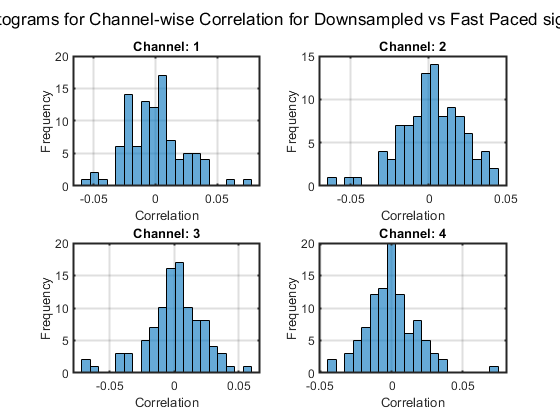

% Histograms for Channel-wise Correlation for Downsampled vs Fast Paced signal
figure;
for i = 1:4
    subplot(2, 2, i);
    histogram(corr_downsampled_vs_fast(:, i), 20);
    title(['Channel: ' num2str(i)]);
    xlabel('Correlation');
    ylabel('Frequency');
    set(gca, 'LineWidth', 1.5);
    grid on;
end
sgtitle('Histograms for Channel-wise Correlation for Downsampled vs Fast Paced signal');

### c. Box plot

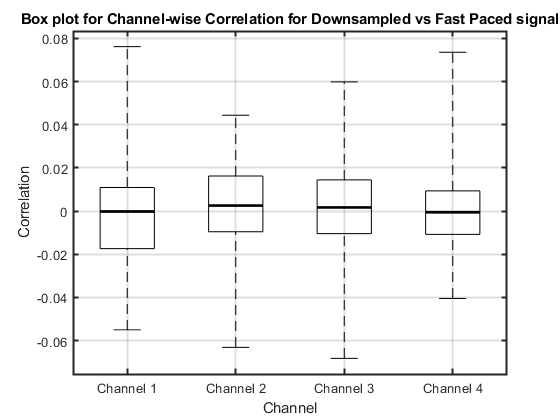

% Box plot for Channel-wise Correlation for Downsampled vs Fast Paced signal
figure;
h = boxplot(corr_downsampled_vs_fast, 'Labels', {'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4'}, 'Colors', 'k', 'Whisker',10);
title('Box plot for Channel-wise Correlation for Downsampled vs Fast Paced signal');
xlabel('Channel');
ylabel('Correlation');

set(findobj(h, 'Tag', 'Median'), 'LineWidth', 2);
set(gca, 'LineWidth', 1.5);
grid on;